# Normal distribution analysis

regularSamples = 100;
fewSamples = 30;
largeSamples = 1000;

## 1 - Different means, tight deviation, same number of samples

mu_1 = -5;
std_1 = 0.3;

mu_2 = 5;
std_2 = 1;
alpha = 0.05;

samples_1 = std_1*randn(1,largeSamples) + mu_1;
samples_2 = std_2*randn(1,largeSamples) + mu_2;

figure
h1 = histogram(samples_1);
hold on
h2 = histogram(samples_2);


[p,h,stats] = ranksum(samples_1,samples_2,"Alpha",alpha,'Tail',"both")

p = 0

h = logical
   1


stats = struct with fields:
       zval: -38.7201
    ranksum: 500500


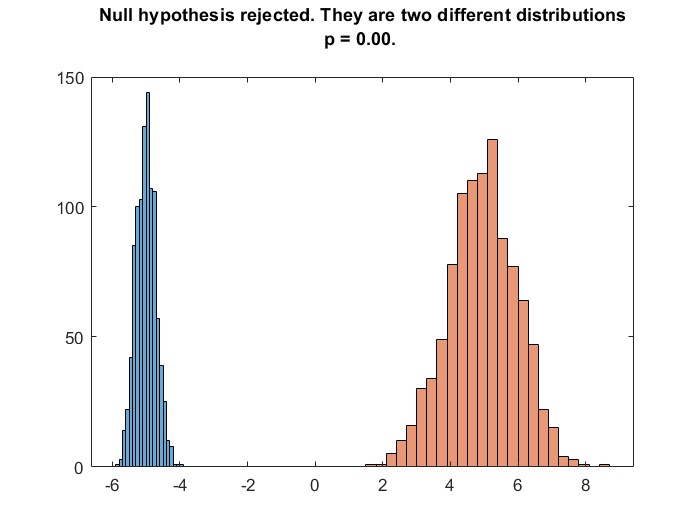

if(h == 1)
    str = sprintf("Null hypothesis rejected. They are two different distributions\n p = %2.2f.  \n",p);
else
    str = sprintf("Null hypothesis accepted. They are the same distribution\n p = %2.2f. \n",p);
end
title(str)

## 2 - Different means, large deviation, same number of samples

mu_1 = -1;
std_1 = 8;

mu_2 = 3;
std_2 = 10;
alpha = 0.05;

samples_1 = std_1*randn(1,largeSamples) + mu_1;
samples_2 = std_2*randn(1,largeSamples) + mu_2;

figure
h1 = histogram(samples_1);
hold on
h2 = histogram(samples_2);


[p,h,stats] = ranksum(samples_1,samples_2,"Alpha",alpha,'Tail',"both")

p = 5.5670e-16

h = logical
   1


stats = struct with fields:
       zval: -8.0984
    ranksum: 895923


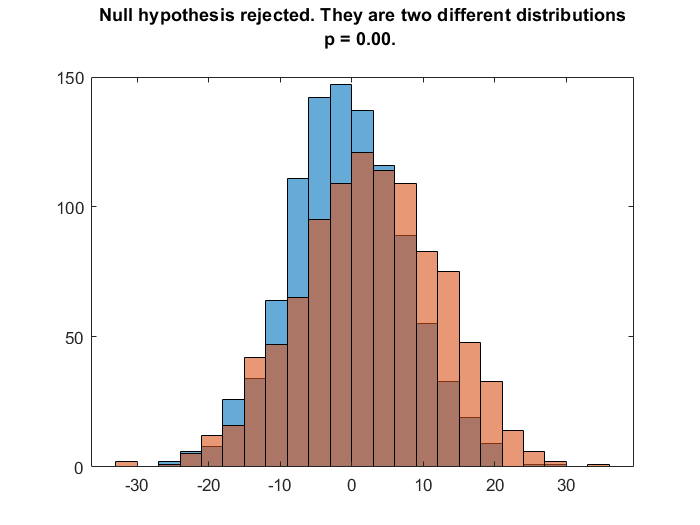

if(h == 1)
    str = sprintf("Null hypothesis rejected. They are two different distributions\n p = %2.2f.  \n",p);
else
    str = sprintf("Null hypothesis accepted. They are the same distribution\n p = %2.2f. \n",p);
end
title(str)

## 3 - Similar means, large deviation, same number of samples

mu_1 = -0.1;
std_1 = 3;

mu_2 = -0.14;
std_2 = 4;

alpha = 0.05;

samples_1 = std_1*randn(1,largeSamples) + mu_1;
samples_2 = std_2*randn(1,largeSamples) + mu_2;

figure
h1 = histogram(samples_1);
hold on
h2 = histogram(samples_2);

[p,h,stats] = ranksum(samples_1,samples_2,"Alpha",alpha,'Tail',"both")

p = 0.8193

h = logical
   0


stats = struct with fields:
       zval: 0.2284
    ranksum: 1003450


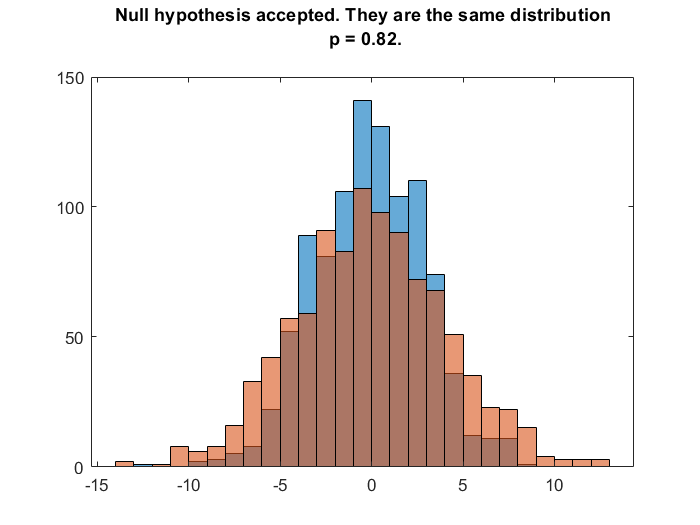

if(h == 1)
    str = sprintf("Null hypothesis rejected. They are two different distributions\n p = %2.2f.  \n",p);
else
    str = sprintf("Null hypothesis accepted. They are the same distribution\n p = %2.2f. \n",p);
end
title(str)

## 4 - Different means, large deviation, different number of samples

mu_1 = -0.1;
std_1 = 3;

mu_2 = 0.5;
std_2 = 2;

alpha = 0.05;

samples_1 = std_1*randn(1,regularSamples) + mu_1;
samples_2 = std_2*randn(1,fewSamples) + mu_2;

figure
h1 = histogram(samples_1);
hold on
h2 = histogram(samples_2);

[p,h,stats] = ranksum(samples_1,samples_2,"Alpha",alpha,'Tail',"both")

p = 0.4025

h = logical
   0


stats = struct with fields:
       zval: -0.8372
    ranksum: 6398


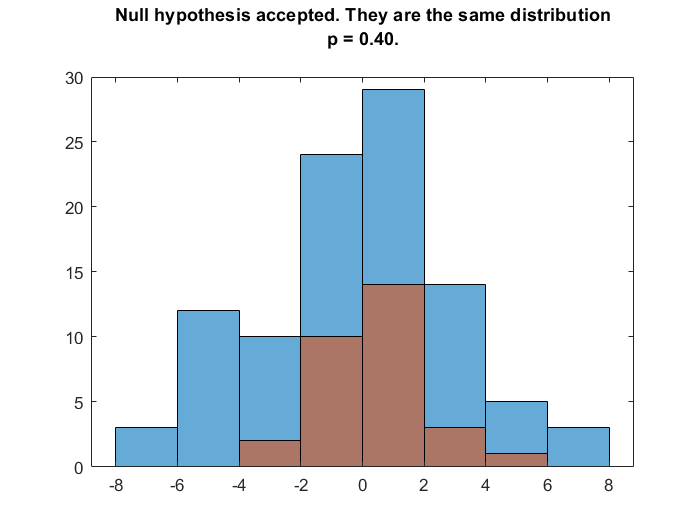

if(h == 1)
    str = sprintf("Null hypothesis rejected. They are two different distributions\n p = %2.2f.  \n",p);
else
    str = sprintf("Null hypothesis accepted. They are the same distribution\n p = %2.2f. \n",p);
end
title(str)